# Adaptive filter results

## Model input

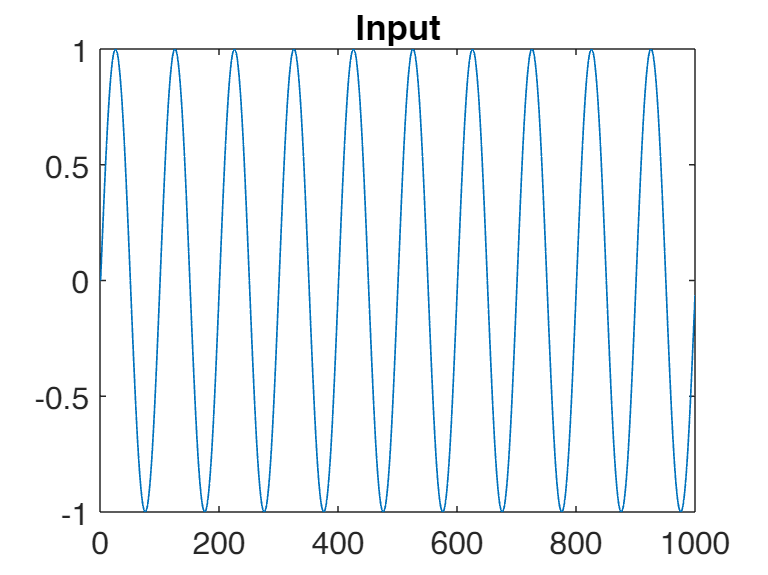

frac_bits = 15;
max_range = 2^frac_bits - 1;
freq = 10;
fs=1000;
samples=1000;

t = 0:1/fs:(samples - 1) / fs;
input = sin(2*pi*freq*t);
desired = cos(2*pi*freq*t);

plot(input);
title("Input")

## Model results

lms = dsp.LMSFilter('Method', 'LMS', 'Length', 2, 'StepSize', 0.01);
[mse, meanw, w, ~] = msesim(lms, input, desired);
w

w = 1.0e-18 *

   -0.6620         0


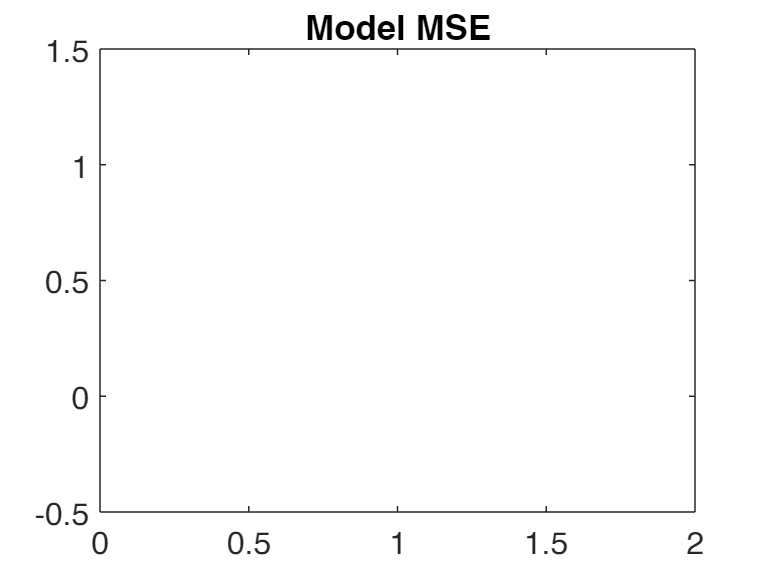

plot(mse)
title("Model MSE")

## Simulation results

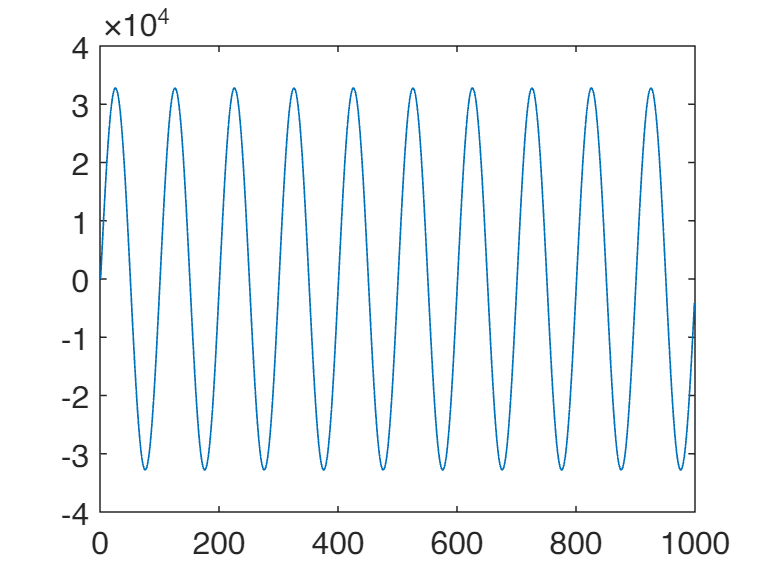

f_in = fopen("../input.txt", "r");
in = fscanf(f_in, "%f\n");
plot(in)

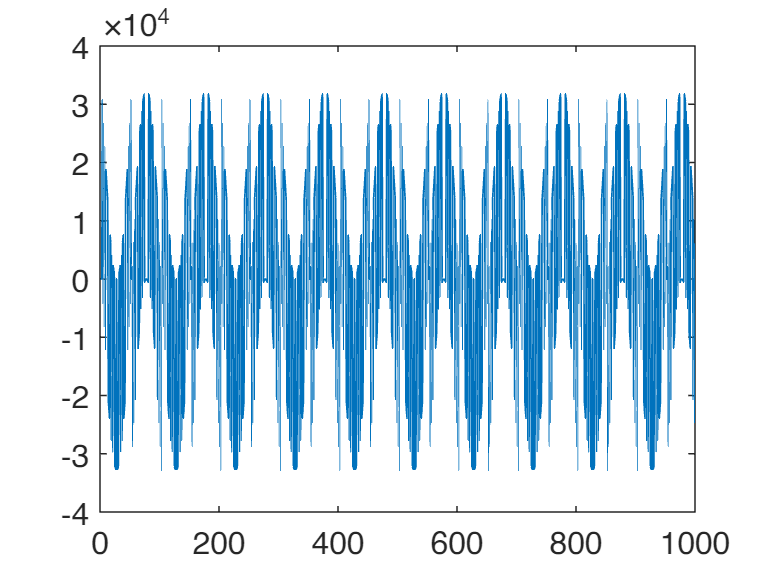

f_out = fopen("../output.txt", "r");
out = fscanf(f_out, "%f\n");
plot(out)